# Predict Damage Costs of Storm Events 

## Introduction

There are a number of ways to approach a predictive modeling problem:

- Curve fitting

- Classification 

- Regression

- Deep learning

- System identification

- Econometrics time-series modeling (ARIMA, GARCH, ..)

See the documentation for examples for the various types of models. For example there are many included at the links below:

[https://mathworks.com/help/deeplearning/examples.html](https://in.mathworks.com/help/deeplearning/examples.html)

[https://mathworks.com/help/stats/examples.html](https://mathworks.com/help/stats/examples.html)

Here, we will use regression to predict the damage cost based on storm event information and use the Regression Learner App to train and validate several regression models.

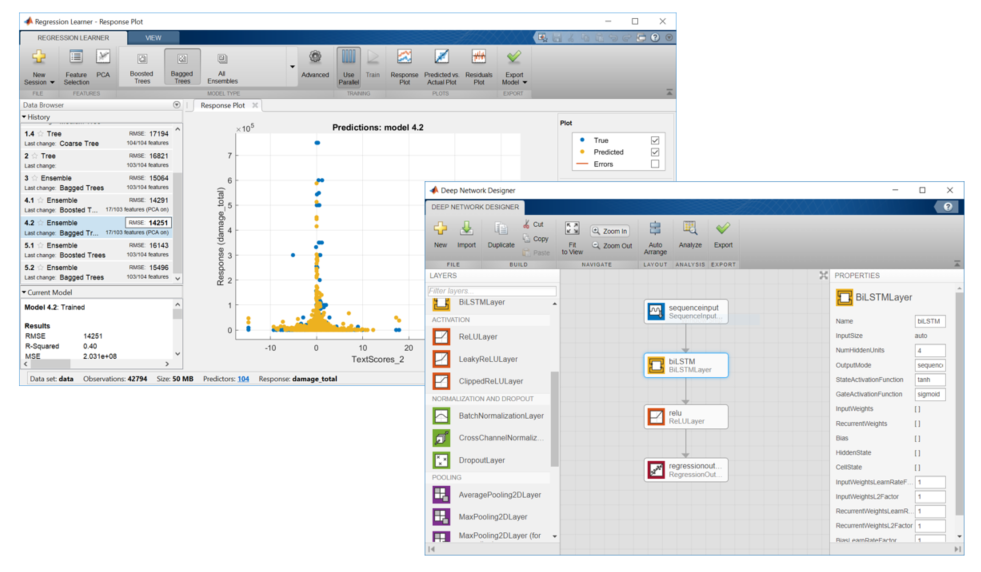

## Prepare data for machine learning

Load the data preprocessed in the previous steps.

load preprocessedDataAll.mat

### Represent dates and times

Represent time as a predictor by considering separate date components. Ensure the data are numeric and convert duration times.

data = timetable2table(data);
[data.yy,data.MM,data.dd] = ymd(data.begin_timestamp);
data.storm_duration = hours(data.storm_duration);

### Remove infrequent classes

Remove data with infrequent categories to make it more reasonable (require certain number of each). Find the classes containing fewer than a certain number of observations.

infrequentClasses = eventTypes.Type(eventTypes.Counts < 210);

Remove these infrequent classes from the data. Use `removecats` to remove the unused categories.

idxInfrequent = ismember(string(data.weathercats),infrequentClasses);
data(idxInfrequent,:) = [];
data.weathercats = removecats(data.weathercats);

### Partition data into training and test sets

Use less data overall, then split into two sets.

rng(1234)
cv = cvpartition(data.weathercats,"Holdout",0.4);
dataTrain = data(cv.training,:);
dataTest = data(cv.test,:);

## Train regression model

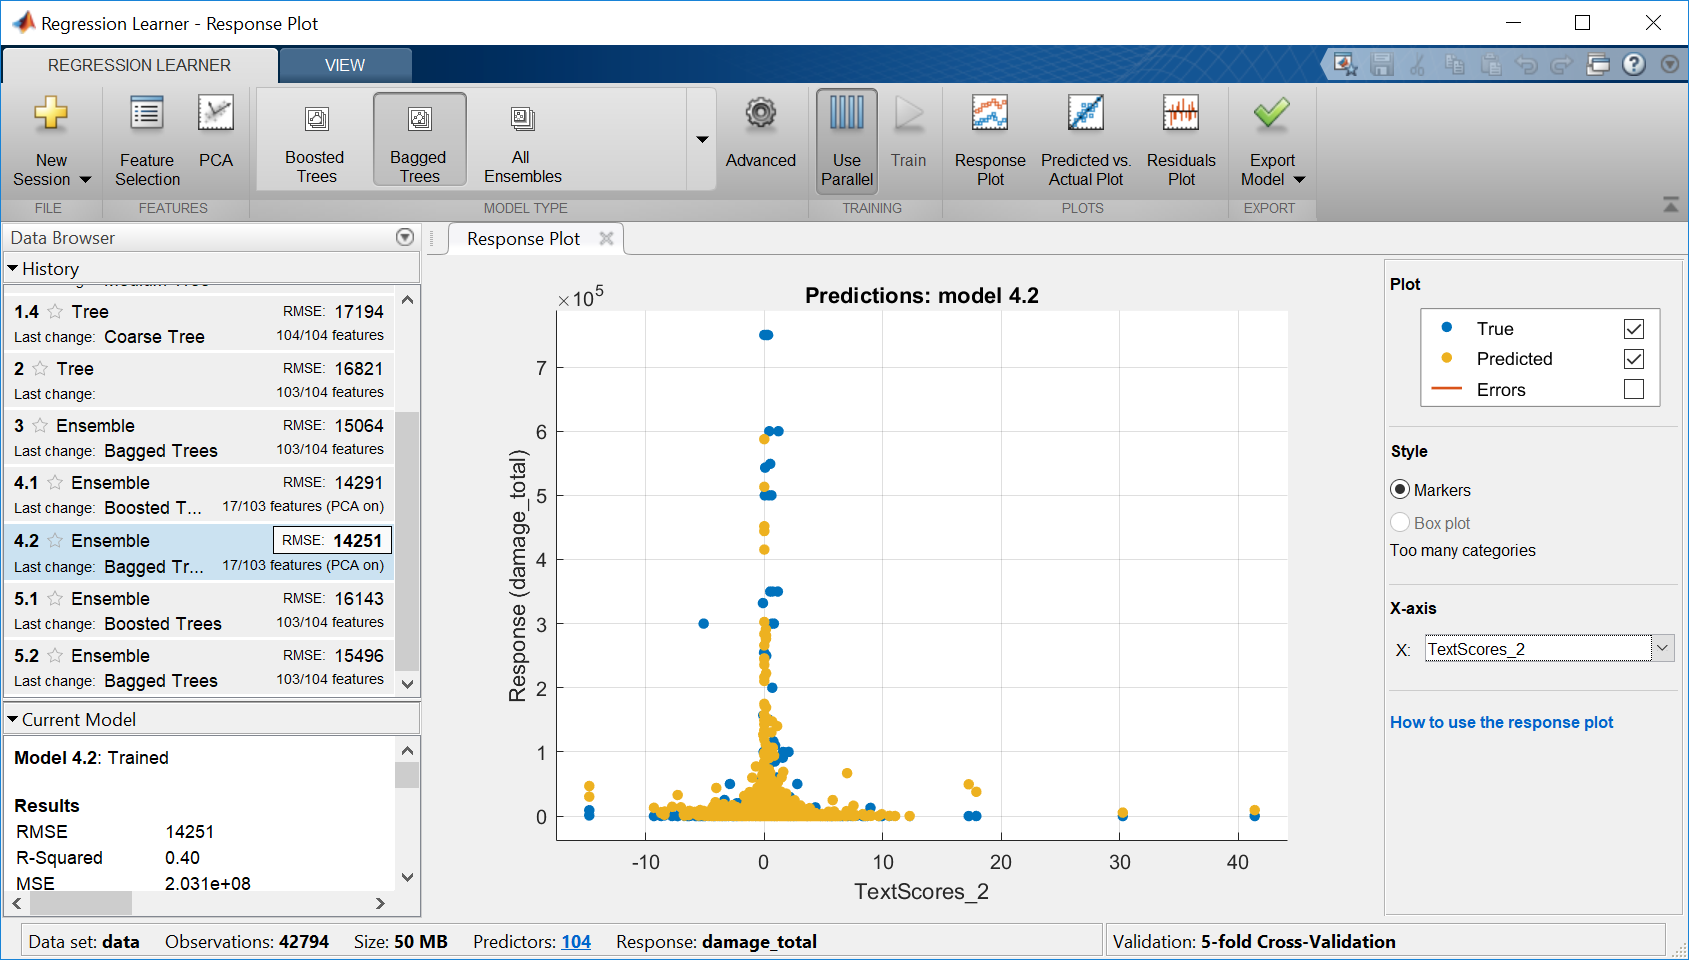

Use Regression Learner to predict damage cost. Use the state, weather event category (`weathercats`), and date components as predictors. 

% regressionLearner

Choose the best classification model. Save the model in a .mat file and generate code to repeat the steps. You can use the model to get a prediction based on new data.

% save MLModel trainedModel 

## Test model

Try the model on the test data. To make predictions with the model, call the predict function (copy and paste the code printed on the command line after exporting the model from the app). 

load MLModel
yfit = trainedModel.predictFcn(dataTest); 

Visualize resulting errors with a histogram.

err = yfit - dataTest.damage_total;
histogram(err)
xlim([-1e4 1e4])
title("Prediction Error")

Test the model with new data as it would be incoming. Use the predictor variables and data types expected by the model. 

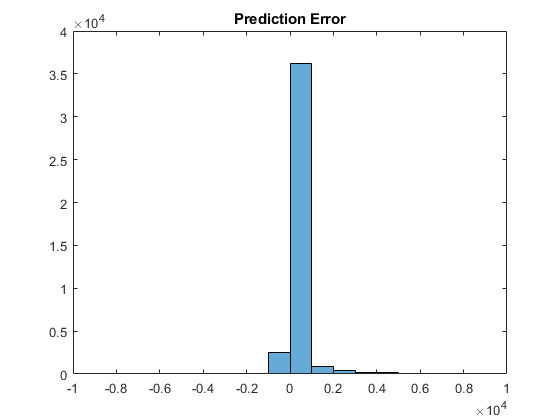

ev = "Tornado";
loc = "MASSACHUSETTS";
testData = table;
testData.weathercats = categorical(ev);
testData.state = categorical(loc);
testData.storm_duration = 1;
testData.Time = datetime("now");
[testData.yy,testData.MM,testData.dd] = ymd(testData.Time);

Predict the damage cost.

dmg = trainedModel.predictFcn(testData); 
disp("Predicted cost of " + ev + ...
    " in " + loc +": $ "+string(dmg)+" K")

Predicted cost of Tornado in MASSACHUSETTS: $ 519.8702 K


Now this model can be used in an application to predict cost based on these variables. See `CreateWebApplication.mlx`.

*Copyright 2018 - 2020 The MathWorks, Inc.*